clc;
clear;
rng(1);
dcl_init;
hder_bit = repmat(reshape(de2bi(hex2dec(['1C6387FF5DA4FA325C895958DC5']'))', [], 1),1,k);
[b_tx] = bit_gen(pkt_size - length(hder_bit),k);
b_tx = [hder_bit; b_tx];
encode_gray_flg = 0;
b_gray = gray_code(k,encode_gray_flg)

b_gray =      0     0
     0     1
     1     0
     1     1


sym_idx=symidx(b_tx,b_gray)

sym_idx =      3
     0
     0
     0
     0
     0
     3
     3
     0
     3


[cons, Es_avg] = constellation(M,modulation)

cons =    1.0000 + 0.0000i
   0.0000 + 1.0000i
  -1.0000 + 0.0000i
  -0.0000 - 1.0000i


Es_avg = 1

sym_mod = symmode(sym_idx,cons) 

sym_mod =   -0.0000 - 1.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i
  -0.0000 - 1.0000i
   1.0000 + 0.0000i
  -0.0000 - 1.0000i


[smpl_tx, cons] = pulse_modulation(sym_idx,modulation, ...
                                            M, fs, smpl_per_symbl, ...
                                               pulse_name ,pulse_gen_mode)

smpl_tx =    0.0000 + 0.0000i
  -0.0000 - 0.1508i
  -0.0000 - 0.3015i
  -0.0000 - 0.4523i
  -0.0000 - 0.6030i
  -0.0000 - 0.4523i
  -0.0000 - 0.3015i
  -0.0000 - 0.1508i
   0.0000 + 0.0000i
   0.1508 + 0.0000i


cons =    1.0000 + 0.0000i
   0.0000 + 1.0000i
  -1.0000 + 0.0000i
  -0.0000 - 1.0000i


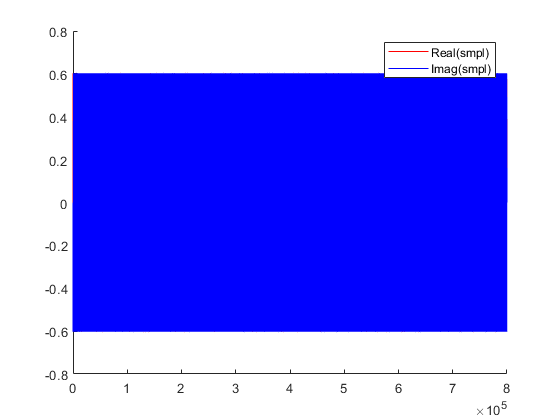

hold on
plot(real(smpl_tx),'red')     
plot(imag(smpl_tx),'blue')
legend('Real(smpl)','Imag(smpl)')

Eb = Es_avg/k; 
SNR_B = 0.3;
SNR_linear = 10^SNR_B; 
var_noise = Eb / SNR_linear;

chnl_delay_in_smpl = 0;
chnl_phase_offset = 0;
[tx_smpl_delayed,rx_smpl,rx_smpl_noise] = channel(smpl_tx,chnl_delay_in_smpl,chnl_phase_offset,var_noise,pkt_size*smpl_per_symbl)

tx_smpl_delayed =    0.0000 + 0.0000i
  -0.0000 - 0.1508i
  -0.0000 - 0.3015i
  -0.0000 - 0.4523i
  -0.0000 - 0.6030i
  -0.0000 - 0.4523i
  -0.0000 - 0.3015i
  -0.0000 - 0.1508i
   0.0000 + 0.0000i
   0.1508 + 0.0000i


rx_smpl =    0.0000 + 0.0000i
  -0.0000 - 0.1508i
  -0.0000 - 0.3015i
  -0.0000 - 0.4523i
  -0.0000 - 0.6030i
  -0.0000 - 0.4523i
  -0.0000 - 0.3015i
  -0.0000 - 0.1508i
   0.0000 + 0.0000i
   0.1508 + 0.0000i


rx_smpl_noise =   -0.1349 + 0.8876i
   0.5424 - 0.0913i
  -0.4404 - 0.7740i
   0.0238 - 1.0610i
   0.2443 - 0.9192i
   0.0725 - 0.3053i
  -0.3047 - 0.0671i
   0.3014 - 0.0754i
   0.0051 + 0.4512i
  -0.2707 - 0.2876i


[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise,modulation, M, fs, ...
                                    smpl_per_symbl,pulse_name,rx_type,pkt_size)

det_sym_idx =      4
     1
     1
     1
     1
     1
     4
     4
     4
     4


rx_sym =    0.0935 - 1.4509i
   1.0592 + 0.1608i
   1.6117 - 0.6769i
   0.8514 - 0.3580i
   1.3570 - 0.4736i
   1.6783 + 0.3684i
   0.5139 - 0.8455i
   0.2632 - 1.4344i
   0.7321 - 0.7562i
  -0.1010 - 1.2169i


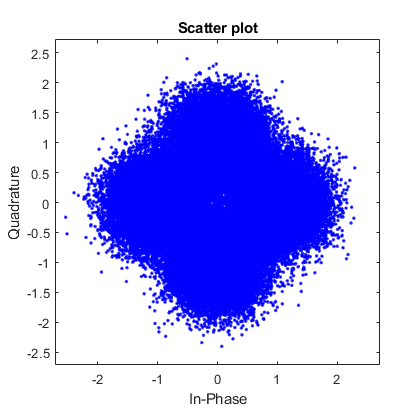

 scatterplot(rx_sym)

[det_bit_dec,det_bit] = decode(det_sym_idx,encode_gray_flg,k)

det_bit_dec =      4
     0
     0
     0
     0
     0
     4
     4
     4
     4


det_bit =      1     1
     0     0
     0     0
     0     0
     0     0
     0     0
     1     1
     1     1
     1     1
     1     1


det_sym_idx = det_sym_idx-1;

Eb = Es_avg/k; 

for i=1:length(snr_db)

SNR_linear = 10^(snr_db(i)/10); 
var_noise = Eb / SNR_linear;


chnl_delay_in_smpl = 0;
chnl_phase_offset = pi/6;

[tx_smpl_delayed,rx_smpl,rx_smpl_noise] = channel(smpl_tx,chnl_delay_in_smpl,chnl_phase_offset,var_noise,pkt_size*smpl_per_symbl);

[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise,modulation, M, fs, ...
                                    smpl_per_symbl,pulse_name,rx_type,pkt_size);
                                
[det_bit_dec,det_bit] = decode(det_sym_idx,encode_gray_flg,k);
det_sym_idx = det_sym_idx-1;


BER(i,1) = sum((b_tx(:)~=det_bit(:)))/(k*pkt_size);

end

if modulation=='psk'
EbNo = (0:10)';
BERawgn = berawgn(EbNo,modulation,M,'nondiff');
else
BERawgn = berawgn(EbNo,modulation,M)
end

NO DELAY

% for i=1:length(snr_db)
% 
% SNR_linear = 10^(snr_db(i)/10); 
% var_noise = Eb / SNR_linear;
% 
% 
% chnl_delay_in_smpl = round(0.8 * smpl_per_symbl);
% chnl_phase_offset = 0;
% 
% [tx_smpl_delayed,rx_smpl,rx_smpl_noise] = channel(smpl_tx,chnl_delay_in_smpl,chnl_phase_offset,var_noise,pkt_size*smpl_per_symbl);
% 
% [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise,modulation, M, fs, ...
%                                     smpl_per_symbl,pulse_name,rx_type,pkt_size);
%                                 
% [det_bit_dec,det_bit] = decode(det_sym_idx,encode_gray_flg,k);
% det_sym_idx = det_sym_idx-1;
% 
% 
% BER(i,1) = sum((b_tx(:)~=det_bit(:)))/(k*pkt_size);
% 
% end
% 
% if modulation=='psk'
% EbNo = (0:10)';
% BERawgn = berawgn(EbNo,modulation,M,'nondiff');
% else
% BERawgn = berawgn(EbNo,modulation,M)
% end

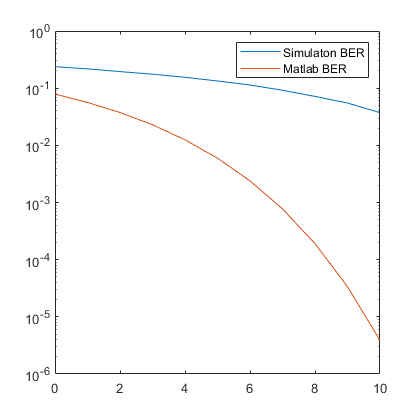

semilogy(0:10,[BER BERawgn])
legend('Simulaton BER','Matlab BER')

SER = sum((sym_idx~=det_sym_idx))/pkt_size

SER = 0.7519

lenght_header = length(hder_bit) * smpl_per_symbl

lenght_header = 864

header_tx_smpl = smpl_tx(1:lenght_header,1);
[corrrr , lags] = xcorr(rx_smpl, header_tx_smpl);
corrrr = corrrr(lags>0);
[amp, start_point] = max(abs(corrrr));
ang_cmpnst = angle(corrrr(start_point,1))

ang_cmpnst = 0.5236

rx_smpl = rx_smpl / amp;
rx_smpl_compensated = rx_smpl(start_point:end,1);
rx_smpl_compensated = rx_smpl_compensated * exp(-1i*ang_cmpnst);

[corrrr , lags] = xcorr(rx_smpl_compensated, header_tx_smpl);
corrrr = corrrr(lags>0);
[~, start_point] = max(abs(corrrr));
ang_cmpnst = angle(corrrr(start_point,1))

ang_cmpnst = 5.3707e-17

Eb = Es_avg/k; 

for i=1:length(snr_db)

SNR_linear = 10^(snr_db(i)/10); 
var_noise = Eb / SNR_linear;


chnl_delay_in_smpl = 10;
chnl_phase_offset = pi/6;

[tx_smpl_delayed,rx_smpl,rx_smpl_noise] = channel(smpl_tx,chnl_delay_in_smpl,chnl_phase_offset,var_noise,pkt_size*smpl_per_symbl);

[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl_noise,modulation, M, fs, ...
                                    smpl_per_symbl,pulse_name,rx_type,pkt_size);
                                
[det_bit_dec,det_bit] = decode(det_sym_idx,encode_gray_flg,k);
det_sym_idx = det_sym_idx-1;


BER(i,1) = sum((b_tx(:)~=det_bit(:)))/(k*pkt_size);

end

if modulation=='psk'
EbNo = (0:10)';
BERawgn = berawgn(EbNo,modulation,M,'nondiff');
else
BERawgn = berawgn(EbNo,modulation,M)
end


function [b] = bit_gen(N,k)
b = randi([0 1],N,k);
end

function [b_gray] = gray_code(k,encode_gray_flg)

if encode_gray_flg==1
if k == 1
    b_gray = [0;1];
else
    z=zeros(2^(k-1),1);
    o = ones(2^(k-1),1);
    rec = gray_code(k-1,encode_gray_flg);
    recB =  rec(end:-1:1,:);
    b_gray = [z,rec;o,recB];
end
else
    b_gray =  0:2^k -1 ;
    b_gray = decimalToBinaryVector(b_gray);
end
end

function sym_idx = symidx(b_tx,b_gray)
sym_idx=zeros(size(b_tx,1),1);
for i=1:size(b_tx,1)
    a = prod(b_tx(i,:)==b_gray,2);
    sym_idx(i) = find(a==1) - 1;
end
end

function [cons, Es_avg] = constellation(M, modulation)
modulation = lower(modulation);
switch modulation
    case 'pam'
        cons = (-(M-1):2:(M-1))';
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
    case 'psk'
        s_i = cos(2*pi/M*(0:(M-1)))';
        s_q = sin(2*pi/M*(0:(M-1)))';
        cons = complex(s_i, s_q);
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
        cons = cons(:);
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
     case 'qam'
         if mod(log2(M),2) == 0
            m = (-sqrt(M) + 1 : 2 : sqrt(M) - 1).';
            cons_old = m + (1j * m).';
            cons = cons_old;
            for i =1:1:sqrt(M)
                if(mod(i,2) == 0)
                    cons(:,i) = flip(cons_old(:,i));
                else
                    cons(:,i) = (cons_old(:,i));
                end
            end
            cons = cons(:);
        else
            m1 = floor(log2(M) / 2);
            m2 = log2(M) - m1;
            cons = (-2 ^ m2 + 1 : 2 : 2 ^ m2 - 1) + ... 
                                (1j * (-2 ^ m1 + 1 : 2 : 2 ^ m1 - 1)).';
            cons = cons(:);
        end
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
        
end
end

function [p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin)
t = transpose(0:1/fs:(smpl_per_symbl-1)/fs);
Ts = smpl_per_symbl/fs;
switch pulse_name
    case 'triangular'
        p = max((Ts/2)-abs(t-(Ts/2)), 0);
        p = p / sqrt(sum(abs(p).^2));
end
end

function sym_mode = symmode(sym_idx,cons) 
for i=1:size(sym_idx,1)
    sym_mode(i,1) = cons(sym_idx(i)+1);
end
end

function [tx_out, cons] = pulse_modulation(sym_idx, modulation, ...
                                            M, fs, smpl_per_symbl, ...
                                               pulse_name , pulse_shape_mode, ...
                                               varargin)
[cons, Es_avg] = constellation(M, modulation);                                         
[p, t] = pulse_shape(pulse_name, fs, smpl_per_symbl, varargin);
sym_mode = symmode(sym_idx,cons);
sym_mode_up = upsample(sym_mode,smpl_per_symbl);
sym_mode_up = sym_mode_up(1:end-(smpl_per_symbl-1),1);
switch (pulse_shape_mode)   
    case 'kron'
        tx_out=kron(sym_mode,p);
    case 'conv'
        tx_out=conv(sym_mode_up,p);
end                                        
end

function [rx_sym] = corr_match(rx_smpl, p, smpl_per_symbl, rx_mode)
rx_sym = zeros(10,1);
switch rx_mode
    case 'correlator'
        for i=1:10 
          corrx = p'*rx_smpl(smpl_per_symbl*(i-1)+1:smpl_per_symbl*(i));
          rx_sym(i,1) = corrx;  
        end
    case 'matched_filter'
        r = conv(p(end:-1:1,1),rx_smpl);
        for (j=1:10)
         rx_sym(j,1)= r(j*smpl_per_symbl,1);   
        end
        
end
end

function [det_sym] = min_dist_detector(rx_sym,constellation)
dist = (rx_sym - constellation.').^2;
[~,det_sym] =  min(dist,[],2);
end


function [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, ...
                                    smpl_per_symbl, pulse_name , rx_mode,N, varargin)

                                
t = transpose(0:1/fs:(smpl_per_symbl-1)/fs);
Ts = smpl_per_symbl/fs;
switch pulse_name
    case 'triangular'
        p = max((Ts/2)-abs(t-(Ts/2)), 0);
        p = p / sqrt(sum(abs(p).^2));
end

rx_sym = zeros(N,1);
switch rx_mode
    case 'correlator'
        for i=1:N 
          corrx = p'*rx_smpl(smpl_per_symbl*(i-1)+1:smpl_per_symbl*(i));
          rx_sym(i,1) = corrx;  
        end
    case 'matched_filter'
        r = conv(p(end:-1:1,1),rx_smpl);
        for (j=1:N)
         rx_sym(j,1)= r(j*smpl_per_symbl,1);   
        end
        
end

switch modulation
    case 'pam'
        m = transpose(1:M);
        cons = 2 * m - 1 - M;
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
    case 'psk'
        s_i = cos(2*pi/M*(0:(M-1)))';
        s_q = sin(2*pi/M*(0:(M-1)))';
        cons = complex(s_i, s_q);
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
        cons = cons(:);
        cons = cons/sqrt(abs(cons'*cons)/M);
        Es_avg = abs(cons'*cons)/M;
     case 'qam'
         if mod(log2(M),2) == 0
            m = (-sqrt(M) + 1 : 2 : sqrt(M) - 1).';
            cons_old = m + (1j * m).';
            cons = cons_old;
            for i =1:1:sqrt(M)
                if(mod(i,2) == 0)
                    cons(:,i) = flip(cons_old(:,i));
                else
                    cons(:,i) = (cons_old(:,i));
                end
            end
            cons = cons(:);
        else
            m1 = floor(log2(M) / 2);
            m2 = log2(M) - m1;
            cons = (-2 ^ m2 + 1 : 2 : 2 ^ m2 - 1) + ... 
                                (1j * (-2 ^ m1 + 1 : 2 : 2 ^ m1 - 1)).';
            cons = cons(:);
        end
        Es_avg = mean(abs(cons).^2);
        cons = cons / sqrt(Es_avg);
        Es_avg = mean(abs(cons).^2);
        
end


dist = (rx_sym - cons.').^2;
[~,det_sym_idx] =  min(dist,[],2);

end

function [tx_smpl_delayed,rx_smpl,rx_smpl_noise] = channel(tx_smpl,chnl_delay_in_smpl,chnl_phase_offset,variance,N)
 temp = zeros(chnl_delay_in_smpl,1);
 tx_smpl_delayed = [temp;tx_smpl];
 rx_smpl = tx_smpl_delayed.*exp(1i*chnl_phase_offset);
 noise_smpl = sqrt(variance/2) * (randn(1,length(rx_smpl))+ 1i *randn(1,length(rx_smpl))).';
 rx_smpl_noise = rx_smpl + noise_smpl;
end

function [det_bit_dec,det_bit] = decode(det_sym_idx,encode_gray_flg,k)
    b_gray = gray_code(k,encode_gray_flg);
    det_bit = [];
    det_bit_dec = 0;
    for i=1:k
        b(:,i) = b_gray(det_sym_idx,i);
        det_bit = [det_bit b(:,i)];
        det_bit_dec = det_bit_dec + det_bit(:,i)*2;
    end
   
end